# Chronic Kidney Disease SVM Classifier

## Samuel Ndirangu 

Github: [https://github.com/SamNdirangu/](https://github.com/SamNdirangu/)

LinkedIn: [https://www.linkedin.com/in/samndirangu](https://www.linkedin.com/in/samndirangu)

Date: 29/04/2019

**Introduction**

This dataset features diagnostic data of early stage chronic kidney disease collected from an Indian population. The dataset has a total of 400 samples each with 24 features. Of the features, 11 are numeric values while 13 are categorical values and certain samples do have certain missing data. Each sample is then classed in one of two classes, having CKD or not having CKD. This data set can then be used in the creation of model to diagnose a patient with chronic Kidney with the given features.

**References and Dataset source ** 

L.Jerlin (2015). UCI Machine Learning Repository [ [https://archive.ics.uci.edu/ml/datasets/chronic_kidney_disease](https://archive.ics.uci.edu/ml/datasets/chronic_kidney_disease) ]. Irvine, CA: University of California, School of Information and Computer Science

## Step 1: Dataset Preparation

Here we prepare our data so that it can be fed to the svm accordingly.

The data is first loaded from an excel xlsx file and the necessry collumns extracted.

The data is also shuffled up so as to avoid any variance or bias problems that may arise.

## File Upload

%The prefix ckd refers to Chronic Kidney Disease
%Stores our file name and path
[file,path] = uigetfile({'*.xlsx';'*.csv'},'Select Data File')

file = 'ckd.xlsx'

path = 'C:\Users\Mheshimiwa\ML Projects\Chronic Kidney Disease\'

selectedfile = fullfile(path,file);
opts = detectImportOptions(selectedfile); %Auto Load options for it
temp_data = readtable(selectedfile,opts); %Read the xlsx file and store it.

data = table2cell(temp_data); %Convert our table to a cell array for ease of access

%Get our feature names
data_feature_names = cellstr(strrep(temp_data.Properties.VariableNames,'_',' '));
sample_no = size(data,1) %Get the number of all diagnosis

sample_no = 400

%Create our X and Y for SVM Training
rand_num = randperm(sample_no); % Permutate numbers upto 569 randomly, This works as shuffling our rows

%Due to data type conflicts group to index all character and categorical values
X_temp(400,24) = 0;
for count=1:10
    count2 = 14 + count;
    X_temp(:,count2) = grp2idx(data(:,count2));
end

%Load our X with features
rand_num = randperm(sample_no); % Permutate numbers upto the number of samples randomly, This works as shuffling our rows
X_temp(:,1:14) = cell2mat(data(:,1:14));
X = X_temp(rand_num(1:end),:);

noFeatures = size(X,2);

%Check if Missing values in collumns containing numerical values and fill in with mean
X(:,1:14) = fillmissing(X(:,1:14),'movmean',10);


%Load our Y with our classes.
[Y_temp,ckd_Y_labels] = grp2idx(data(:,25));
Y = Y_temp(rand_num(1:end),:);
ckd_Y_labels %Display our class labels

ckd_Y_labels = 2×1 cell array
    {'ckd'   }
    {'notckd'}


## Step 2: Perform Cross Validation  : K-fold 10

To reduce any underfitting or overfitting that may occur during testing the data is cross validated using K-Fold 10 times. The folds are stratified ensuring a uniform distribution of each class with in each fold further lowering any data bias that would have been present.

%Validate now the training set using Kfold 10 times
CV = cvpartition(Y,'KFold',10,'Stratify',true);


## Step 3: Feature Ranking

This steps ranks our feature and creates a feature sets consisting  a given number of all the features from 1 feature to all features of the dataset

We use sequential FS and loop it a number of times equal to the number of features filling in a logical matrix of features.

opts = statset('display','iter','UseParallel',true); %Sets the display option
rng(5); %This sets our random state.

fun = @(train_data, train_labels, test_data, test_labels)...
    sum(predict(fitcsvm(train_data, train_labels,'Standardize',true,'KernelFunction','gaussian'), test_data) ~= test_labels);

%Rank our features using Sequential FS forward selection
%Inside history we store the ranking of features
[fs, history] = sequentialfs(fun, X, Y, 'cv', CV, 'options', opts,'nfeatures',noFeatures);

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.
Step 1, added column 11, criterion value 0.1
Step 2, added column 3, criterion value 0.045
Step 3, added column 21, criterion value 0.0275
Step 4, added column 4, criterion value 0.0125
Step 5, added column 9, criterion value 0.0075
Step 6, added column 2, criterion value 0.0075
Step 7, added column 5, criterion value 0.0075
Step 8, added column 6, criterion value 0.0075
Step 9, added column 8, criterion value 0.0075
Step 10, added column 10, criterion value 0.0075
Step 11, added column 12, criterion value 0.01
Step 12, added column 22, criterion value 0.01
Step 13, added column 20, criterion value 0.0125
Step 14, added column 18, criterion value 0.015
Step 15, added column 19, criterion value 0.015
Step 16, added column 7, criterion value 0.02
Step 17, added column 15, criterion value 

## Step 4: Kernel and Feature Selection

This step now analyzes each kernel functions performance in regard to a given feature set

rng(3);
ave_Accuracy(noFeatures,6) = 0; %Initializes where we'll store our performance for each feature set and kernel
for count=1:noFeatures
    %MStore our best features
    ave_Accuracy(count,1) = count;
    
    %Linear
    analyzing_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'linear','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    ave_Accuracy(count,2) = (1 - kfoldLoss(analyzing_Model, 'LossFun', 'ClassifError'))*100;
    
    %rbf training
    analyzing_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'rbf','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    ave_Accuracy(count,3) = (1 - kfoldLoss(analyzing_Model, 'LossFun', 'ClassifError'))*100;
    
    %Gaussian
    analyzing_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'gaussian','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    ave_Accuracy(count,4) = (1 - kfoldLoss(analyzing_Model, 'LossFun', 'ClassifError'))*100;
    
    %Polynomial
    analyzing_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'polynomial','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    ave_Accuracy(count,5) = (1 - kfoldLoss(analyzing_Model, 'LossFun', 'ClassifError'))*100;
    
    %Polynomial power 3
    analyzing_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'polynomial','Standardize',true,'KernelScale','auto','PolynomialOrder',3);
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    ave_Accuracy(count,6) = (1 - kfoldLoss(analyzing_Model, 'LossFun', 'ClassifError'))*100;
end

## Visualize Results

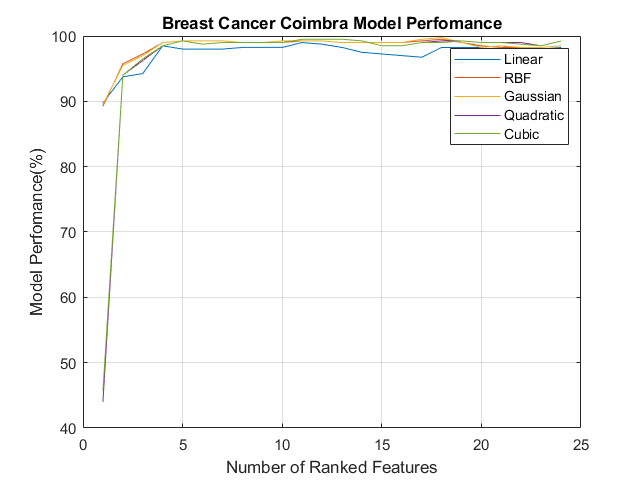

figure
plot(ave_Accuracy(:,2:6))
title('Breast Cancer Coimbra Model Perfomance')
xlabel('Number of Ranked Features')
ylabel('Model Perfomance(%)')
legend('Linear','RBF','Gaussian','Quadratic','Cubic')
grid on;

## Step 5: Model Selection: Best Hyperparameters

We now need to search for the best hyperparameters for the highest accuracy perfomance for the dataset.The following functions will be utilized to tune the SVM parameters C and Kernel function variables We use fitcsvm and train using the best features obtained from step 4. The kernel function is selected from the best perfoming Kernel in the previous step

%The best observed Kernel is a gaussian

%To lower our false negative rate we introduce a cost parameter
% to increase the cost of misclassifying Malignant as Benign
cost.ClassNames = {'2' '1'};
cost.ClassificationCosts = [0 1;1 0];

rng(3);
%For the bayesain optimizer we let it use the defaults but increase its Maximum Objective evaluations to 80
SVM_Model = fitcsvm(X(:,history.In(18,:)),Y,'KernelFunction','gaussian','Cost',cost,'Standardize',true,...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',struct('UseParallel',true,...
    'ShowPlots',false,'MaxObjectiveEvaluations',80,'Repartition',true));

Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstrain-|  KernelScale |
|      | workers | result |             | runtime     | (observed)  | (estim.)    | t            |              |
|===============================================================================================================|
|    1 |       2 | Best   |     0.37343 |     0.18334 |     0.37343 |     0.37343 |      0.26653 |    0.0025451 |
|    2 |       2 | Best   |    0.017544 |     0.22813 |    0.017544 |     0.04279 |       5.8664 |       1.3003 |
|    3 |       2 | Accept |     0.36341 |     0.12818 |    0.017544 |    0.042108 |       102.69 |       632.51 |
|    4 |       2 | Accept |     0.37343 |      0.1863 |    0.017544 |    0.044365 |     0.015849 |     0.079124 |
|  

## Step 6: Train a SVM and Evaluate Validation Loss : Kernel Gaussian

%Pass on our X and Y to the SVM classifier.
rng(3); %seeds our random generator allowing for reproducibility of results
%Box Costraint is our penalty factor C, the higher the stricter the hyperplane
constraint = SVM_Model.BoxConstraints(1,:);
kernelScale = SVM_Model.KernelParameters.Scale;

%To lower our false negative rate we introduce a cost parameter
% to increase the cost of misclassifying Malignant as Benign
cost.ClassNames = {'1' '2'};
cost.ClassificationCosts = [0 29;1 0];

%using a polynomial kernel
best_SVMModel = fitcsvm(X(:,history.In(18,:)),Y,'CVPartition',CV,'KernelFunction',...
    'gaussian','Standardize',true,'BoxConstraint',constraint,'KernelScale',kernelScale,'Cost',cost);

%This averages our cross validated models loss. The lower the better the prediction
% Compute validation accuracy
SVM_ValidationAccuracy = (1 - kfoldLoss(best_SVMModel, 'LossFun', 'ClassifError'))*100

SVM_ValidationAccuracy = 99.9730

%This averages our cross validated models loss. The lower the better the prediction
bc_ModelLoss = kfoldLoss(best_SVMModel)

bc_ModelLoss = 2.7031e-04

## Step 7: Evaluate the model's perfomance using a confusion Matrix

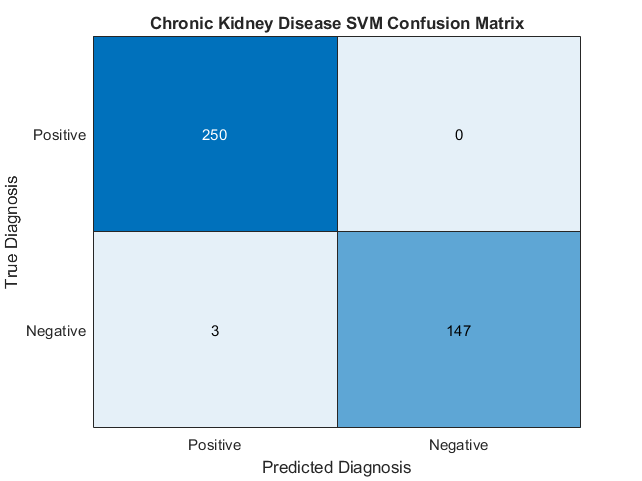

[Y_pred, validationScores] = kfoldPredict(best_SVMModel);
conMat=confusionmat(Y,Y_pred);
%Generate a Confusion Matrix
%The confusion matrix gives us a view of the rate of true positives to false negatives.
%It enables to have proper view of how effecive our model is in prediction of illness minimizing of having false negatives
conMatHeat = heatmap(conMat,'Title','Chronic Kidney Disease SVM Confusion Matrix','YLabel','True Diagnosis','XLabel','Predicted Diagnosis',...
    'XDisplayLabels',{'Positive','Negative'},'YDisplayLabels',{'Positive','Negative'},'ColorbarVisible','off');

## Step 8: Train a Random Forest Decision Tree and Evaluate Validation Loss 

%Pass on our X and Y to the Ensembler
rng(3); %seeds our random generator allowing for reproducibility of results

X_raw = temp_data(:,1:24);


%To lower our false negative rate we introduce a cost parameter
% to increase the cost of misclassifying Malignant as Benign
cost.ClassNames = {'2' '1'};
cost.ClassificationCosts = [0 2.5;1 0];



template = templateTree(...
    'MaxNumSplits', 200);
treeModel = fitcensemble(X(:,history.In(24,:)),Y, ...
    'Method', 'Bag', ...
    'NumLearningCycles', 44, ...
    'Learners', template,'CVPartition',CV,'Cost',cost,'CategoricalPredictors',[15,16,17,18,19,20,21,22,23,24]);

% Perform cross-validation
%partitionedModel = crossval(trainedClassifier.ClassificationEnsemble,);

%This averages our cross validated models loss. The lower the better the prediction
% Compute validation accuracy
validationAccuracy = (1 - kfoldLoss(treeModel, 'LossFun', 'ClassifError'))*100

validationAccuracy = 99

%This averages our cross validated models loss. The lower the better the prediction
bc_ModelLoss = kfoldLoss(treeModel)

bc_ModelLoss = 0.0100

## Step 7: Evaluate the model's perfomance using a confusion Matrix

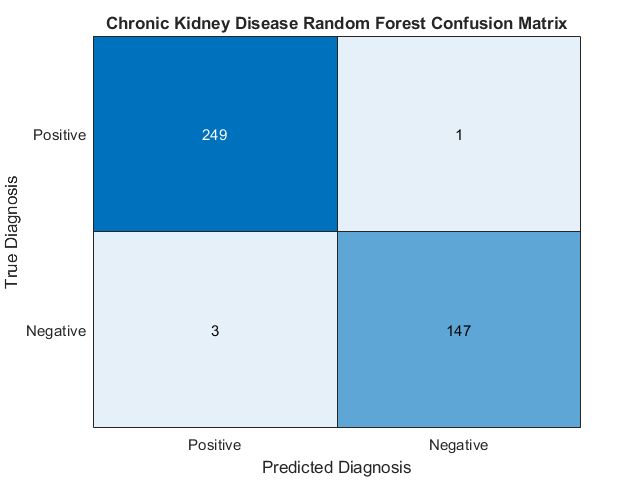

[Y_pred2, validationScores] = kfoldPredict(treeModel);
conMat2=confusionmat(Y,Y_pred2);
%Generate a Confusion Matrix
%The confusion matrix gives us a view of the rate of true positives to false negatives.
%It enables to have proper view of how effecive our model is in prediction of illness minimizing of having false negatives
conMatHeat = heatmap(conMat2,'Title','Chronic Kidney Disease Random Forest Confusion Matrix','YLabel','True Diagnosis','XLabel','Predicted Diagnosis',...
    'XDisplayLabels',{'Positive','Negative'},'YDisplayLabels',{'Positive','Negative'},'ColorbarVisible','off');